## **Heavy Frame**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Fuselage Properties**

D = 6.38;                          % Fuselage diameter (m)
r = D ./ 2;                        % Fuselage radius (m)
C = 2 * pi * r;                    % Fuselage circumference (m)

**0.3 Material Properties**

E_f = 67000000000;                 % Young's Modulus (N/m^2)
rho_f = 2860;                      % Density (kg/m^3)
sigma_y = 614000000;               % Tensile yield stress (Pa)
tau_y = sigma_y ./ sqrt(3);        % Shear yield stress (Pa)

pi * sqrt(E_f/sigma_y)

ans = 32.8173

**0.4 Critical Loading Conditions**

Q = 4.244780666699219e+04;        % Maximum shear force (N)
P = 0;                            % Maximum tangential load (N)
T = 0;                            % Maximum torque (Nm)

### **1 WISE curve**

**1.1 Find WISE curve**

% Define theta range (0 to 2*pi for full fuselage section)
theta = linspace(0, 2 * pi, 1000);

% Compute shear flow distributions for P, Q, and T load cases
M_P = -(P * r / (2 * pi)) .* ((3 * sin(theta) / 2) + (pi - theta) .* (cos(theta) - 1));
N_P = -(P / (2 * pi)) .* ((sin(theta) / 2) - (pi - theta) .* cos(theta));
S_P = -(P / (2 * pi)) .* (((pi - theta) .* sin(theta)) - 1 - (cos(theta) / 2));

M_Q = -(Q * r / (2 * pi)) .* ((cos(theta) / 2) - (pi - theta) .* sin(theta) + 1);
N_Q = -(Q / (2 * pi)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_Q = -(Q / (2 * pi)) .* (((pi - theta) .* cos(theta)) - (sin(theta) / 2));

M_T = -(T / (2 * pi)) .* (pi - 2 * sin(theta) - theta);
N_T = -(T / (2 * pi * r)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_T = -(T / (2 * pi * r)) .* (1 + 2 * cos(theta));

% Compute total shear flow distributions
M_total = M_P + M_Q + M_T;
N_total = N_P + N_Q + N_T;
S_total = S_P + S_Q + S_T;

1.2 Plotting the result

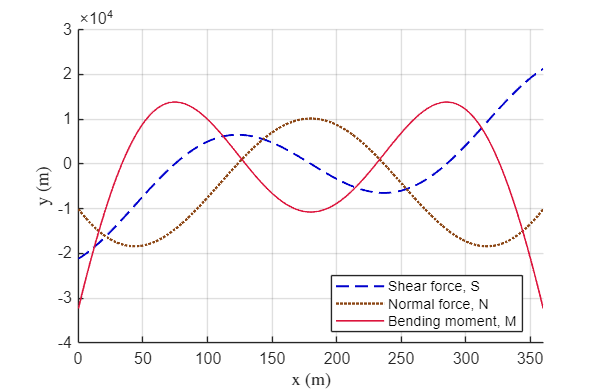

figure(1)

clf;

hold on;

plot(theta * 180 / pi, S_total, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(theta * 180 / pi, N_total, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5);
plot(theta * 180 / pi, M_total, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.);

% Legends
legend("Shear force, S", "Normal force, N", "Bending moment, M", "Location", "best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('x (m)', 'Interpreter', 'latex');
ylabel('y (m)', 'Interpreter', 'latex');

% Set plot limits and grid
xlim([0 360]);
grid on;

hold off;

% Set figure size
set(gcf, 'Position', [0 0 500 325]);

1.3 Find the maximum

S_max = max(abs(S_total))

S_max = 2.1224e+04

N_max = max(abs(N_total))

N_max = 1.8430e+04

M_max = max(abs(M_total))

M_max = 3.2326e+04

### **2 Optimisation Problem using fmincon with Global research**

compare [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) with [GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html) and [ga](https://ww2.mathworks.cn/help/gads/ga.html), using the best result

**2.0 Initial conditions**

Define the objective function for optimisation problem

fun = @(x) mass_hf(x(1), x(2), x(3), x(4));            % (t_web, t_fl, b_f, h_f)

Define initial point for the objective function

x0 = [10 / 1000, 10 / 1000, 200 / 1000, 300 / 1000];   % take average from literiture review

Boundary conditions

lb = [1 / 1000, 1 / 1000, 10 / 1000, 10 / 1000];       % change dynamically
ub = [0.05, 0.05, 0.5, 0.5];                           % change dynamically

Nonlinear constraints

nonlcon = @Non_linear_hf_4;

**2.1 Define problem**

Create optimization problem [createOptimProblem](https://ww2.mathworks.cn/help/gads/createoptimproblem.html)

problem = createOptimProblem('fmincon', 'objective', fun, 'x0', x0, 'lb', lb, 'ub', ub, 'nonlcon', nonlcon, 'options', optimoptions('fmincon', 'Display', 'iter'));

[GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html)

gs = GlobalSearch('NumTrialPoints', 2000, 'MaxWaitCycle', 100);

**2.2 Run optimisation**

[x_opt, f_opt] = fmincon(fun, x0, [], [], [], [], lb, ub, nonlcon)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     0.0059    0.0087    0.0671    0.0794


f_opt = 93.5801

[x_opt, f_opt] = run(gs, problem);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    4.012681e+02    5.709e+08    8.376e+02
    1      10    3.473791e+02    5.606e+08    1.049e+04    2.435e-02
    2      15    2.468809e+02    5.207e+08    3.198e+04    9.502e-02
    3      20    2.464452e+02    5.203e+08    3.207e+04    4.932e-04
    4      25    2.482065e+02    5.169e+08    3.174e+04    1.282e-02
    5      30    2.481998e+02    5.169e+08    3.174e+04    5.958e-06
    6      35    2.481610e+02    5.166e+08    3.177e+04    8.567e-04
    7      40    2.476416e+02    5.163e+08    3.194e+04    2.754e-04
    8      45    1.632183e+02    4.389e+08    8.104e+04    4.807e-02
    9      50    1.630492e+02    4.387e+08    8.121e+04    1.037e-04
   10      55    1.104624e+02    3.342e+08    1.787e+03    4.107e-03
   11      60    1.099281e+02    3.317e+08    1.886e+03    1.396e-03
   12      65    9.024357e+01    2.040e+08    6

  296    2402    9.107807e+01    9.540e+02    6.552e-01    1.221e-07


  297    2407    9.107877e+01    6.220e+03    6.550e-01    4.882e-07
  298    2412    9.107971e+01    8.862e+02    6.551e-01    1.111e-07
  299    2417    9.108035e+01    5.648e+03    6.549e-01    4.447e-07
  300    2422    9.108120e+01    8.244e+02    6.550e-01    1.012e-07

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  301    2427    9.108178e+01    5.127e+03    6.548e-01    4.046e-07
  302    2432    9.108256e+01    7.683e+02    6.549e-01    9.220e-08
  303    2437    9.108309e+01    4.653e+03    6.547e-01    3.683e-07
  304    2442    9.108380e+01    7.172e+02    6.548e-01    8.398e-08


  305    2447    9.108427e+01    4.222e+03    6.547e-01    3.353e-07


  306    2452    9.108492e+01    6.707e+02    6.547e-01    7.651e-08


  307    2457    9.108536e+01    3.830e+03    6.546e-01    3.044e-07


  308    2462    9.108595e+01    6.284e+02    6.547e-01    6.972e-08


  309    2467    9.108634e+01    3.474e+03    6.546e-01    2.817e-07


  310    2472    9.108688e+01    5.899e+02    6.546e-01    6.354e-08


  311    2477    9.108724e+01    3.151e+03    6.545e-01    2.510e-07
  312    2482    9.108773e+01    5.550e+02    6.546e-01    5.795e-08


  313    2487    9.108806e+01    2.858e+03    5.228e-01    2.301e-07


  314    2492    9.108850e+01    5.231e+02    5.228e-01    5.284e-08


  315    2497    9.108880e+01    2.591e+03    5.228e-01    2.094e-07


  316    2502    9.108921e+01    4.942e+02    5.228e-01    4.820e-08


  317    2507    9.108948e+01    2.350e+03    5.227e-01    1.910e-07


  318    2512    9.108987e+01    4.679e+02    5.228e-01    2.149e-07
  319    2517    9.109009e+01    2.131e+03    5.774e-01    2.924e-07
  320    2522    9.109043e+01    4.440e+02    6.156e-01    4.038e-08
  321    2527    9.109065e+01    1.933e+03    6.543e-01    1.579e-07
  322    2532    9.109096e+01    4.223e+02    6.544e-01    3.678e-08


  323    2537    9.109116e+01    1.754e+03    6.543e-01    1.438e-07


  324    2542    9.109145e+01    4.025e+02    6.543e-01    3.366e-08
  325    2547    9.109163e+01    1.592e+03    6.543e-01    1.309e-07
  326    2552    9.109189e+01    3.846e+02    6.543e-01    3.085e-08
  327    2557    9.109205e+01    1.446e+03    6.542e-01    1.191e-07
  328    2562    9.109229e+01    3.684e+02    6.543e-01    2.830e-08
  329    2567    9.109244e+01    1.314e+03    6.542e-01    1.085e-07
  330    2572    9.109266e+01    3.536e+02    6.542e-01    2.601e-08

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  331    2577    9.109279e+01    1.196e+03    6.542e-01    9.883e-08
  332    2582    9.109299e+01    3.402e+02    6.542e-01    2.394e-08
  333    2587    9.109311e+01    1.090e+03    6.542e-01    9.002e-08
  334    2592    9.109329e+01    3.281e+02    6.542e-01    2.209e-08
  335    2597    9.109340e+01    9.949e+02    6.542e-01    8.202e-08
  336    2602    9.109357e+01    

  344    2642    9.109445e+01    2.828e+02    6.541e-01    1.538e-08


  345    2647    9.109451e+01    6.569e+02    6.541e-01    5.178e-08


  346    2652    9.109463e+01    2.762e+02    6.541e-01    1.446e-08


  347    2657    9.109467e+01    6.115e+02    6.541e-01    4.730e-08


  348    2662    9.109479e+01    2.703e+02    6.541e-01    1.364e-08
  349    2667    9.109482e+01    5.718e+02    6.541e-01    4.324e-08
  350    2672    9.109493e+01    2.650e+02    6.541e-01    1.293e-08
  351    2677    9.109496e+01    5.374e+02    6.541e-01    3.955e-08
  352    2682    9.109506e+01    2.602e+02    6.541e-01    1.231e-08


  353    2687    9.109508e+01    5.077e+02    6.541e-01    3.621e-08


  354    2692    9.109518e+01    2.559e+02    6.541e-01    1.177e-08


  355    2697    9.109520e+01    4.822e+02    6.541e-01    3.320e-08


  356    2702    9.109529e+01    2.520e+02    6.541e-01    1.131e-08
  357    2707    9.109530e+01    4.604e+02    6.541e-01    3.047e-08
  358    2712    9.109539e+01    2.491e+02    6.541e-01    1.092e-08


  359    2717    9.109541e+01    4.496e+02    6.541e-01    8.096e-08


  360    2722    9.109549e+01    2.490e+02    6.541e-01    7.427e-08

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  361    2727    9.109549e+01    4.394e+02    6.541e-01    2.761e-08
  362    2732    9.109558e+01    2.489e+02    6.541e-01    1.063e-08
  363    2737    9.109558e+01    4.297e+02    6.541e-01    2.741e-08
  364    2742    9.109567e+01    2.488e+02    6.541e-01    1.045e-08
  365    2747    9.109567e+01    4.205e+02    6.541e-01    2.673e-08
  366    2752    9.109576e+01    2.486e+02    6.541e-01    1.031e-08
  367    2757    9.109576e+01    4.117e+02    6.541e-01    2.608e-08
  368    2762    9.109584e+01    2.485e+02    6.541e-01    1.018e-08
  369    2767    9.109584e+01    4.034e+02    6.540e-01    2.548e-08
  370    2772    9.109593e+01    2.484e+02    6.541e-01    1.005e-08
  371    2777    9.109593e+01    3.954e+02    6.540e-01    2.491e-08
  372    2782    9.109601e+01    

  388    2862    9.109661e+01    2.474e+02    6.540e-01    9.117e-09


  389    2867    9.109660e+01    3.374e+02    5.220e-01    2.094e-08


  390    2872    9.109668e+01    2.472e+02    5.220e-01    9.083e-09

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  391    2877    9.109667e+01    3.321e+02    5.220e-01    2.069e-08
  392    2882    9.109674e+01    2.471e+02    5.220e-01    8.952e-09
  393    2887    9.109673e+01    3.270e+02    5.220e-01    2.027e-08
  394    2892    9.109681e+01    2.470e+02    5.220e-01    8.873e-09
  395    2897    9.109680e+01    3.221e+02    5.220e-01    1.996e-08
  396    2902    9.109687e+01    2.469e+02    5.220e-01    8.797e-09
  397    2907    9.109687e+01    3.174e+02    5.220e-01    1.966e-08
  398    2912    9.109694e+01    2.468e+02    5.220e-01    8.724e-09


  399    2917    9.109693e+01    3.128e+02    5.220e-01    1.937e-08


  400    2922    9.109700e+01    2.467e+02    5.220e-01    8.653e-09


  401    2927    9.109699e+01    3.084e+02    5.219e-01    1.910e-08


  402    2932    9.109706e+01    2.465e+02    5.219e-01    8.585e-09


  403    2937    9.109705e+01    3.041e+02    5.219e-01    1.882e-08
  404    2942    9.109713e+01    2.464e+02    5.219e-01    8.544e-09


  405    2947    9.109712e+01    2.999e+02    5.219e-01    1.857e-08


  406    2952    9.109719e+01    2.463e+02    5.219e-01    8.454e-09
  407    2957    9.109718e+01    2.959e+02    5.219e-01    1.832e-08
  408    2962    9.109725e+01    2.462e+02    5.219e-01    8.391e-09
  409    2967    9.109723e+01    2.920e+02    5.219e-01    1.808e-08
  410    2972    9.109730e+01    2.461e+02    5.219e-01    8.331e-09
  411    2977    9.109729e+01    2.882e+02    5.219e-01    1.786e-08
  412    2982    9.109736e+01    2.460e+02    5.219e-01    8.272e-09
  413    2987    9.109735e+01    2.846e+02    5.219e-01    1.764e-08
  414    2992    9.109742e+01    2.458e+02    5.219e-01    8.215e-09
  415    2997    9.109741e+01    2.810e+02    5.219e-01    1.742e-08
  416    3002    9.109748e+01    2.457e+02    5.219e-01    8.160e-09

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,


  111     865    9.103483e+01    1.627e+03    6.310e-01    1.658e-07


  112     870    9.103658e+01    7.304e+03    6.311e-01    2.451e-07


  113     875    9.103593e+01    1.588e+03    6.309e-01    5.312e-07


  114     880    9.103751e+01    7.154e+03    5.013e-01    6.166e-07


  115     885    9.103675e+01    1.549e+03    5.012e-01    1.594e-07


  116     890    9.103843e+01    7.007e+03    5.013e-01    2.378e-07


  117     895    9.103768e+01    1.512e+03    5.012e-01    1.551e-07


  118     900    9.103932e+01    6.862e+03    5.355e-01    2.301e-07


  119     905    9.103859e+01    1.475e+03    5.196e-01    1.519e-07
  120     910    9.103994e+01    6.721e+03    6.308e-01    1.290e-06



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
  121     915    9.103948e+01    1.439e+03    5.009e-01    1.222e-06


  122     920    9.104105e+01    6.584e+03    5.009e-01    2.201e-07


  123     925    9.104035e+01    1.403e+03    5.008e-01    1.460e-07
  124     930    9.104189e+01    6.449e+03    5.174e-01    2.171e-07


  125     935    9.104120e+01    1.369e+03    5.007e-01    1.427e-07


  126     940    9.104271e+01    6.316e+03    5.007e-01    2.108e-07



Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.


GlobalSearch stopped because it analyzed all the trial points.

1 out of 4 local solv

### **3 Validate Result**

**3.1 Assign x values**

t_web = x_opt(1); % web thickness (m)
t_web * 1000      % 15-25 mm

ans = 5.8781

t_fl = x_opt(2);  % flange thickness (m)
t_fl * 1000       % 25-40 mm

ans = 8.6873


b_f = x_opt(3);   % frame width (m)
b_f * 1000        % 200-400 mm

ans = 67.0901

h_f = x_opt(4);   % frame height (m)
h_f * 1000        % 300-500 mm

ans = 79.4148

**2.2 Calculate mass**

% Find second moment of inertia
[I_x, A] = I_hf(t_web, t_fl, b_f, h_f);
I_x * 1000 ^ 4

ans = 2.0906e+06


A * 1000 ^ 2

ans = 1.6325e+03


% Calcualte frame mass
m_f = rho_f * A * C

m_f = 93.5801

**2.3 Calculate constraint**

% Slenderness ratio
1.2 * sqrt(E_f/sigma_y)

ans = 12.5353

(h_f / t_web) - 1.2 * sqrt(E_f/sigma_y)

ans = 0.9750

h_f / t_web

ans = 13.5103

0.7 * sqrt(E_f/sigma_y)

ans = 7.3123

(b_f / t_fl) - 0.7 * sqrt(E_f/sigma_y)

ans = 0.4105

b_f / t_fl

ans = 7.7227


%
% Maximum direct stress
N_max / A - sigma_y

ans = -6.0271e+08

(sigma_y)  / 1e6

ans = 614

(N_max / A)  / 1e6

ans = 11.2894


%
% Maximum shear stress
Q_x = b_f * t_fl * (h_f/2 - t_fl/2);
(S_max * Q_x) / (I_x * t_web) - tau_y

ans = -3.1889e+08

tau_y  / 1e6

ans = 354.4931

((S_max * Q_x) / (I_x * t_web)) / 1e6

ans = 35.5985


%
% Maximum bending stress
(M_max * h_f) / (2 * I_x) - sigma_y

ans = -98.2724

sigma_y / 1e6

ans = 614

((M_max * h_f) / (2 * I_x)) / 1e6

ans = 613.9999

### **4 Buckling analysis**

% From ESDU datasheet 
% (see Structure 3 Lecture Notes for k to K calculation)
Kc = 3.69; % 3.62 for v = 0.3
Ks = 4.93; % 4.83 for v = 0.3
% Flange Local Buckling:
BCf = Kc * E_f * ((t_fl / b_f) ^ 2);
BCf / 1e6

ans = 4.1453e+03

% Web Shear Buckling:
BCw = Ks * E_f * ((t_web / h_f) ^ 2);
BCw / 1e6

ans = 1.8096e+03

% Web compressive Buckling:
BCw2 = Kc * E_f * ((t_web / h_f) ^ 2);
BCw2 / 1e6

ans = 1.3545e+03